# Corrélation

clear
Type = 'DCCS1D' ;
Materiau = '4140';
Eprouvette ='0';
Numero = '0';
addpath('/home/tdelaselle/Documents/Codes/Codes persos Matlab/Fonctions');
repertoire_brute = acces_donnees_brutes();
repertoire_traitees = acces_donnees_traitees();
addpath(strcat(repertoire_traitees,'/',Type,'/',Materiau));
addpath(strcat(repertoire_brute,'/',Type,'/',Materiau,'/',Eprouvette,'.',Numero,'/','EA'));
nomWF = strcat(Type,'_',Materiau,'_',Eprouvette,'.',Numero);  %Penser à ajouter strcat(Naming,'_','HDD.TXT') pour charger TDD/HDD/waveforms

WF = zeros(15360,8);
for i = 1:8
    load(strcat(string(i),".mat"));
    WF(1:size(donnees.Amplitude),i) = donnees.Amplitude;
end
% WF(:,1) = donnees.Temps;

Cor = zeros(7,7);
dt = zeros(7,7);
[a,b]=xcorr(WF(7500:end,1),WF(7500:end,5),'normalized')

a =    -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
         0


b =        -7860       -7859       -7858       -7857       -7856       -7855       -7854       -7853       -7852       -7851       -7850       -7849       -7848       -7847       -7846       -7845       -7844       -7843       -7842       -7841       -7840       -7839       -7838       -7837       -7836       -7835       -7834       -7833       -7832       -7831       -7830       -7829       -7828       -7827       -7826       -7825       -7824       -7823       -7822       -7821       -7820       -7819       -7818       -7817       -7816       -7815       -7814       -7813       -7812       -7811


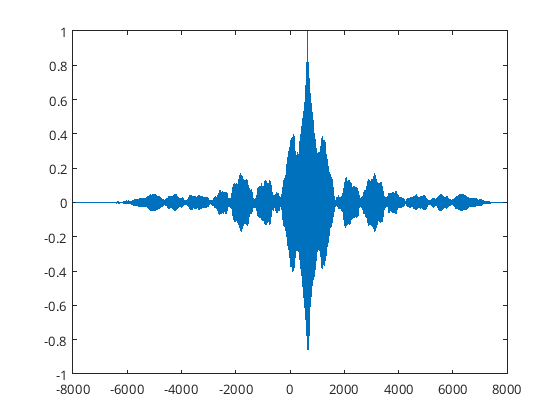

plot(b,a);

[m,x] = max(a)

m = 0.9953

x = 8516

b(x)

ans = 655

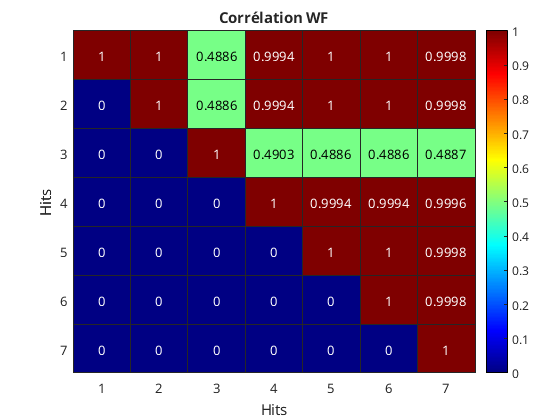

for i = 1:7
%  figure();
%  plot(WF(end-7500:end,i));
    for j = i:7
         [corr, t] = xcorr(WF(:,i),WF(:,j),'normalized');
         [Cor(i,j), x] = max(corr);
         dt(i,j) = t(x);
    end
end
figure();
heatmap(Cor);
colormap jet;
title(strcat('Corrélation WF'));
xlabel('Hits');
ylabel('Hits');
caxis([0 1]);

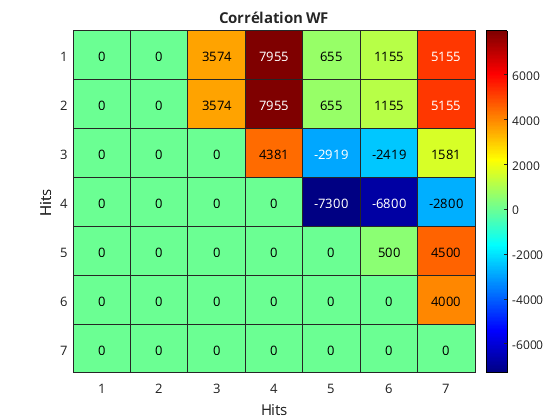

figure();
heatmap(dt);
colormap jet;
title(strcat('Corrélation WF'));
xlabel('Hits');
ylabel('Hits');

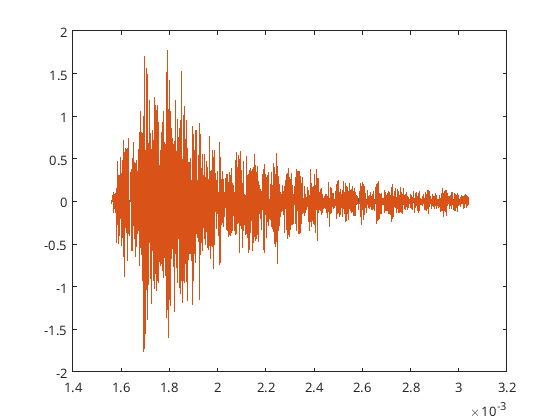

figure();
plot(donnees.Temps,WF(1:size(donnees.Temps),1));
hold on;
plot(donnees.Temps,donnees.Amplitude);